# STIM SIGNAL ANALYSIS

T_6736 = T_slrt(contains(T_slrt.sessionLabel,'6736'),:)

T_6736 = 10×9 table
    trialNum     stimTrace_raw     stimTrace_lowess    responseDelay    responseThreshold    pawSide     QC      sessionType                                    sessionLabel                                
    ________    _______________    ________________    _____________    _________________    _______    _____    ___________    ____________________________________________________________________________

     {[ 2]}     {4001×1 double}    {4001×1 double}      {[2.9360]}         {[0.2600]}         {'L'}     {[0]}    {'vonFrey'}    {'date--2024-03-11_subj--6736-20240310_npxls--R-npx10_phase--L-hind-paw_g0'}
     {[ 5]}     {4001×1 double}    {4001×1 double}      {[

T_6735 = T_slrt(contains(T_slrt.sessionLabel,'6735'),:)

T_6735 = 11×9 table
    trialNum     stimTrace_raw     stimTrace_lowess    responseDelay    responseThreshold    pawSide     QC      sessionType                                    sessionLabel                                
    ________    _______________    ________________    _____________    _________________    _______    _____    ___________    ____________________________________________________________________________

     {[ 1]}     {4001×1 double}    {4001×1 double}      {[ 0.0920]}        {[0.6711]}         {'L'}     {[0]}    {'vonFrey'}    {'date--2024-03-12_subj--6735-20240311_npxls--R-npx10_phase--L-hind-paw_g0'}
     {[ 9]}     {4001×1 double}    {4001×1 double}      {[

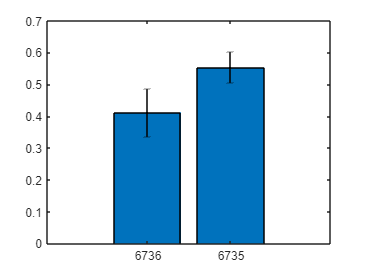

% RESPONSE THRESHOLD
% % subj 6736
response_threshold_6736 = T_6736.responseThreshold;
response_threshold_mean_6736 = mean(cell2mat(response_threshold_6736),1);
response_threshold_std_6736 = std(cell2mat(response_threshold_6736));
% % subj 6735
response_threshold_6735 = T_6735.responseThreshold;
response_threshold_mean_6735 = mean(cell2mat(response_threshold_6735),1);
response_threshold_std_6735 = std(cell2mat(response_threshold_6735));
% % plot results
avg = [response_threshold_mean_6736; response_threshold_mean_6735];
stdev = [response_threshold_std_6736; response_threshold_std_6735];
figure;
x = [1,2];
xLabel = ["6736","6735"];
bh = bar(x, avg); 
hold on
er = errorbar(x, avg, stdev);
er.LineStyle = 'none';
er.Color = [0 0 0];
set(gca,"XTickLabel",xLabel);

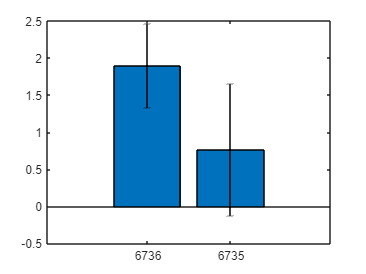

% RESPONSE DELAY
% % subj 6736
response_delay_6736 = T_6736.responseDelay;
response_delay_mean_6736 = mean(cell2mat(response_delay_6736),1);
response_delay_std_6736 = std(cell2mat(response_delay_6736));
% % subj 6735
response_delay_6735 = T_6735.responseDelay;
response_delay_mean_6735 = mean(cell2mat(response_delay_6735),1);
response_delay_std_6735 = std(cell2mat(response_delay_6735));
% % plot results
avg = [response_delay_mean_6736; response_delay_mean_6735];
stdev = [response_delay_std_6736; response_delay_std_6735];
figure;
x = [1,2];
xLabel = ["6736","6735"];
bh = bar(x, avg); 
hold on
er = errorbar(x, avg, stdev);
er.LineStyle = 'none';
er.Color = [0 0 0];
set(gca,"XTickLabel",xLabel);

% STIM PLOTS (PEAK ALIGNED)
